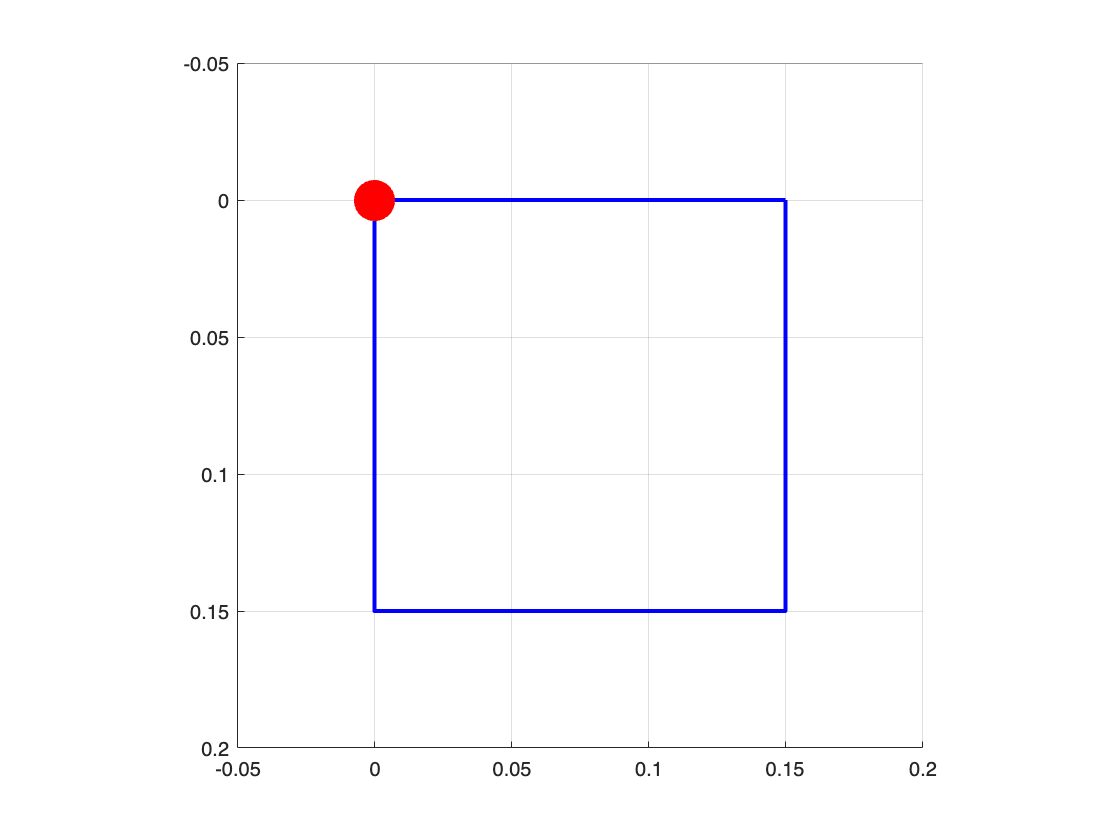

clear all
close all;
clc;

% calcolo traiettoria p_desired dp_desired e vettore dei tempi t
Quadrato;

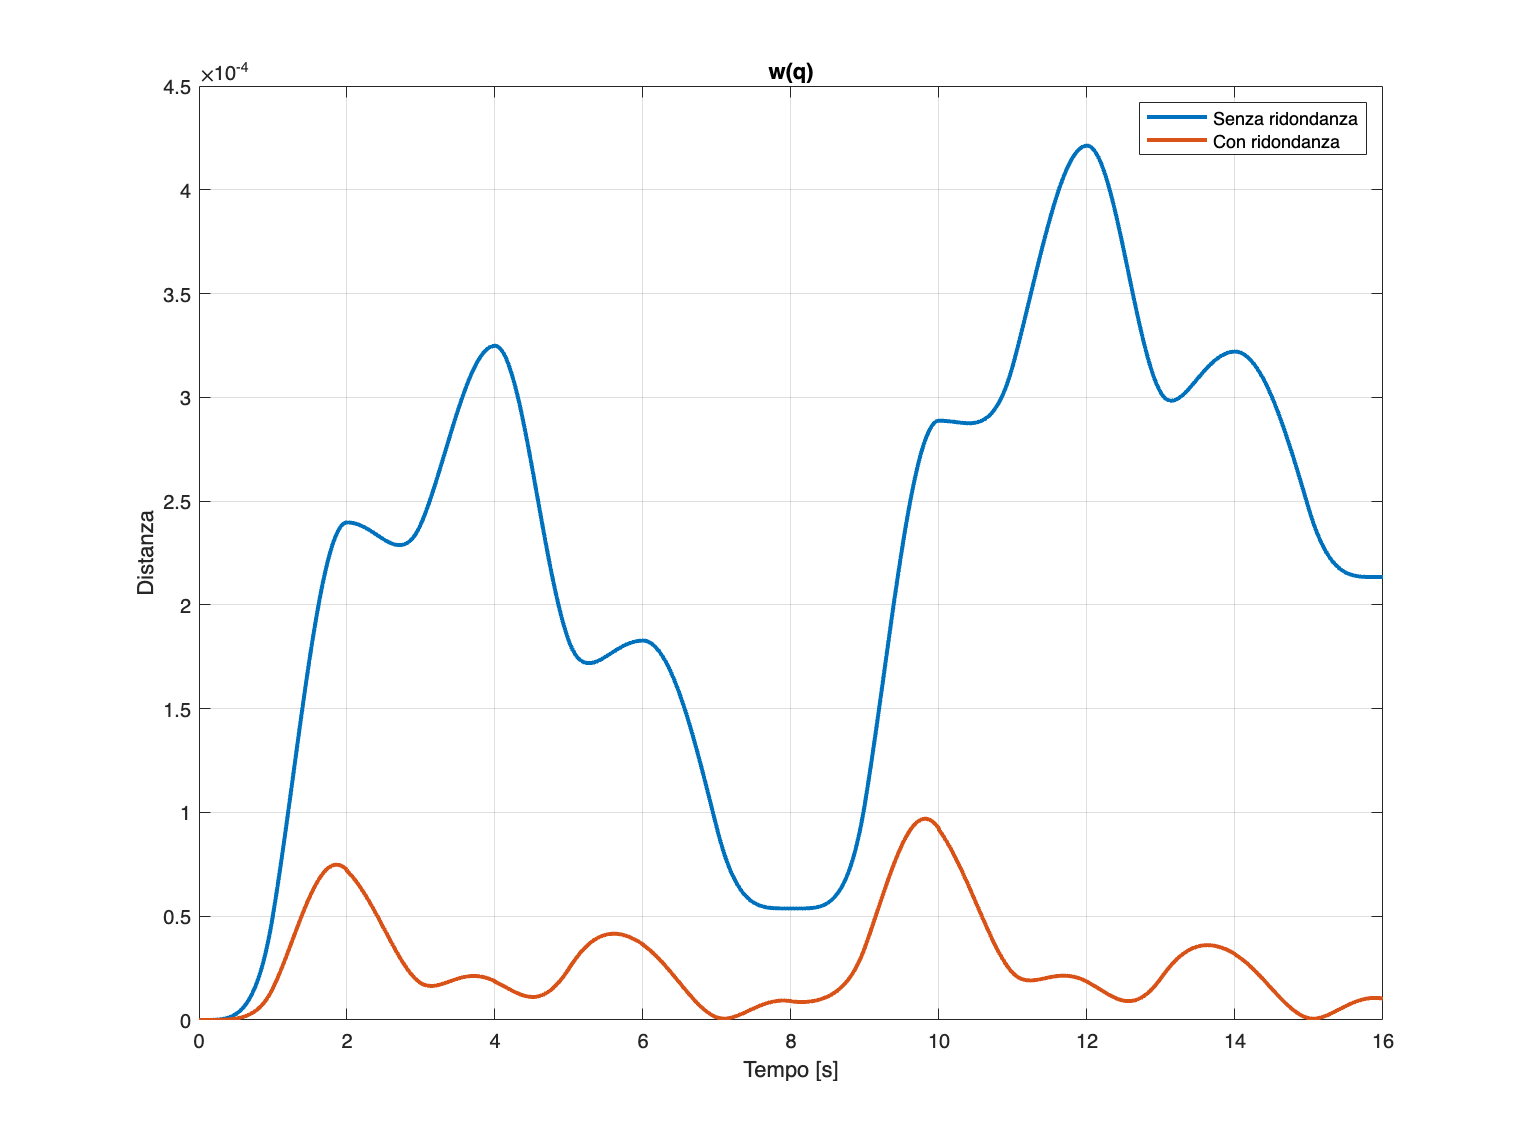

% doppio giro
p_desired = [p_desired p_desired];
dp_desired = [dp_desired dp_desired];
tt = t+4*tfl;
t = [t tt]; 


N = length(t);            % Numero di punti della simulazione 
n = 7;                    % Numero di articolazioni
q = zeros(n, N);          % Posizioni delle articolazioni nel tempo
dq= zeros(n, N);          % Velocità desiderate delle articolazioni nel tempo
dq_0 = zeros(n, N);       % Vettore velocità nello spazio nullo dello Jacobiano

p_current = zeros(3, N);
error = zeros(3,N);

w = zeros(1, N);
grad_w = zeros(1,n);

%definizione guadagno CLIK
K=100;
% Definisco il valore di k0 per il calcolo di dq_0
k0=200; 
 
% Definizione della matrice DH iniziale(presa dal sito di Cassino)

DH_initial = [
    0, -pi/2, 0.2755, 77*pi/180;
    0, pi/2, 0, -17*pi/180;
    0, pi/2, -0.410, 0;
    0, pi/2, -0.0098, 43*pi/180;
    0, pi/2, -0.3111, -94*pi/180;
    0, pi/2, 0, 77*pi/180;
    0, 0, 0.2638, 71*pi/180
];

q0 = DH_initial(:,4);

% Configurazione iniziale del braccio (in radianti)
%q_initial(:, 1) = [77; -17; 0; 43; -94; 77; 71] * pi/180;


% Calcolo della posizione iniziale dell'organo terminale utilizzando la cinematica diretta
T_initial = DirectKinematics(DH_initial);
T_initial_7 = T_initial(:, :, 7); %trasformazione omogenea dell'organo terminale
p_initial = T_initial_7(1:3, 4); %estraggo la posizione iniziale della punta dell'organo terminale,
                                     %considerando solo le prime tre righe dell'ultima colonna (la quarta) della matrice T_initial_7.


% traiettoria a partire dalla posizione iniziale
p_desired = p_initial + p_desired;


% Limiti di escursione dei giunti in rad
q_max = [180; 180; 180; 180; 180; 180; 180] * pi / 180 + q0; 
q_min = [-180; -180; -180; -180; -180; -180; -180] * pi / 180 + q0; 

% Calcolo del valore medio della corsa per ciascuna variabile di giunto
q_mean = (q_max + q_min) / 2;

%Inizializzazione p_current, DH_current, q
p_current(:, 1) = p_initial;
DH_current = DH_initial;
q(:,1) = DH_initial(:,4);

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ciclo con ridondanza
%%%%%%%%%%%%%%%%%%%%%%%%%%%

for i = 1:N
         
    % Calcolo della distanza dai fine corsa w(q)
    for j = 1:2
         w(i) = w(i) + (q(j,i) - q_mean(j))^2/(q_max(j) - q_min(j))^2;
    end
    w(i) = -w(i)/2/n;
    
  
    % Calcolo del gradiente di w(q) rispetto a q
    for j = 1:2
       grad_w(j) = -((q(j,i) - q_mean(j))/(q_max(j) - q_min(j))^2)/n;
    end

    % Calcolo di dq0
    dq_0(:, i) = k0 * (grad_w)';
   
    % Calcolo dell'errore come differenza tra la posizione desiderata e la posizione attuale
    error(:,i) = p_desired(:,i) - p_current(:,i);
    
    % Implementazione dell'algoritmo di cinematica inversa con guadagno K=2
    J = Jacobian(DH_current); % Calcolo del Jacobiano per l'organo terminale
    
    % Considera solo le velocità di traslazione
    J_trans = J(1:3, :);

    %Algoritmo di cinematica inversa
    pinvJ = pinv(J_trans);
    dq(:, i) = pinvJ * (dp_desired(:,i) + K * error(:,i)) + (eye(n) - pinvJ * J_trans) * dq_0(:, i);
   
    % Aggiornamento delle posizioni delle articolazioni,integrazione
    if i < N
        q(:, i+1) = q(:, i) + Ts * dq(:, i); % Utilizza Ts * dq_desired del passo temporale corrente

        % Calcolo la matrice DH corrente utilizzando le nuove posizioni delle articolazioni
        DH_current(:,4) = q(:,i+1);
        
        % Calcola la trasformazione omogenea del robot utilizzando la matrice DH corrente
        T_current = DirectKinematics(DH_current);
        
        % Estrai la posizione corrente dell'organo terminale dalla trasformazione omogenea
        p_current(:, i+1) = T_current(1:3, 4, 7);
    
    end
    
end


% salvataggio variabili con ridondanza
qr = q;
dqr = dq;

p_currentr = p_current;
errorr = error;

wr = w;

%{
% Plot di w(q) 
figure;
for j = 1:n
    subplot(n, 1, j);
    plot(t, w, 'b', 'LineWidth', 1.5);
    title(['Fine Corsa Giunto ', num2str(j)]);
    legend('w(q)');
    grid on;
end
xlabel('Tempo [s]');
ylabel('w(q)');

% Plot di q_1 e q
figure('Position', [100, 100, 800, 600]);
for j = 1:n
    subplot(n, 1, j);
    hold on;
    plot(t, q_1(j, :), 'r', 'LineWidth', 1.5);
    title(['Giunto ', num2str(j)]);
    legend('q');
    grid on;
end
xlabel('Tempo [s]');
ylabel('Posizione [rad]');

%{
%plot di q_1
figure('Position', [100, 100, 800, 600]);
for j = 1:n
    subplot(n, 1, j);
    hold on;
    plot(t, q_1(j, :), 'r', 'LineWidth', 1.5);
    title(['Giunto ', num2str(j)]);
    legend('q_1');
    grid on;
end
xlabel('Tempo [s]');
ylabel('Posizione [rad]');

%plot di q
figure('Position', [100, 100, 800, 600]);
for j = 1:n
    subplot(n, 1, j);
    hold on;
    plot(t, q(j, :), 'r', 'LineWidth', 1.5);
    title(['Giunto ', num2str(j)]);
    legend('q');
    grid on;
end
xlabel('Tempo [s]');
ylabel('Posizione [rad]');
%}

% Plot delle velocità desiderate dei giunti nel tempo
figure;
subplot(3,1,1);
plot(t, dq);
title('Velocità dei giunti');
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
legend('Giunto 1', 'Giunto 2', 'Giunto 3', 'Giunto 4', 'Giunto 5', 'Giunto 6', 'Giunto 7');

% Plot delle posizioni desiderate dei giunti nel tempo
subplot(3,1,2);
plot(t, q);
title('Posizioni desiderate dei giunti');
xlabel('Tempo [s]');
ylabel('Posizione [rad]');
legend('Giunto 1', 'Giunto 2', 'Giunto 3', 'Giunto 4', 'Giunto 5', 'Giunto 6', 'Giunto 7');

% Plot della posizione corrente dell'organo terminale
subplot(3,1,3);
plot(t, p_current(1,:), 'b--', 'LineWidth', 1.5); % Posizione corrente lungo l'asse X
hold on;
plot(t, p_current(2,:), 'r--', 'LineWidth', 1.5); % Posizione corrente lungo l'asse Y
plot(t, p_current(3,:), 'g--', 'LineWidth', 1.5); % Posizione corrente lungo l'asse Z
plot(t, p_desired(1,:), 'b', 'LineWidth', 1.5); % Posizione desiderata lungo l'asse X
plot(t, p_desired(2,:), 'r', 'LineWidth', 1.5); % Posizione desiderata lungo l'asse Y
plot(t, p_desired(3,:), 'g', 'LineWidth', 1.5); % Posizione desiderata lungo l'asse Z
title('Posizione corrente e desiderata dell''organo terminale');
xlabel('Tempo [s]');
ylabel('Posizione [m]');
legend('X Corrente', 'Y Corrente', 'Z Corrente', 'X Desiderata', 'Y Desiderata', 'Z Desiderata');


% Plot delle componenti dell'errore nel tempo
figure;
subplot(3,1,1);
plot(t, error(1,:), 'r-', 'LineWidth', 1.5); % Errore lungo l'asse X
title('Errore lungo l''asse X');
xlabel('Tempo [s]');
ylabel('Errore [m]');

subplot(3,1,2);
plot(t, error(2,:), 'g-', 'LineWidth', 1.5); % Errore lungo l'asse Y
title('Errore lungo l''asse Y');
xlabel('Tempo [s]');
ylabel('Errore [m]');

subplot(3,1,3);
plot(t, error(3,:), 'b-', 'LineWidth', 1.5); % Errore lungo l'asse Z
title('Errore lungo l''asse Z');
xlabel('Tempo [s]');
ylabel('Errore [m]');
%}


%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ciclo senza ridondanza (k0 = 0)
%%%%%%%%%%%%%%%%%%%%%%%%%%%

% inizializzazione p_current, DH_current, q
p_current(:, 1) = p_initial;
DH_current = DH_initial;
q(:,1) = DH_initial(:,4);

w = zeros(1, N);
grad_w = zeros(1,n);

k0 = 0;

for i = 1:N 

    % Calcolo della distanza dal centro corsa w(q)
    for j = 1:n
         w(i) = w(i) + (q(j,i) - q_mean(j))^2/(q_max(j) - q_min(j))^2;
    end
    w(i) = -w(i)/2/n;

    % calcolo del gradiente di w(q) rispetto a q
    for j = 1:n
       grad_w(j) = -((q(j,i) - q_mean(j))/(q_max(j) - q_min(j))^2)/n;
    end

    % calcolo di dq0
    dq_0 = k0*grad_w';

    % Calcolo dell'errore come differenza tra la posizione desiderata e la posizione attuale
    error(:,i) = p_desired(:,i) - p_current(:,i);

    % Implementazione dell'algoritmo di cinematica inversa con guadagno K=2
    J = Jacobian(DH_current); % Calcolo del Jacobiano per l'organo terminale
    
    % Considera solo le velocità di traslazione
    J_trans = J(1:3, :);

    %Algoritmo di cinematica inversa
    pinvJ = pinv(J_trans);
    dq(:, i) = pinvJ*(dp_desired(:,i) + K*error(:,i)) + (eye(n) - pinvJ*J_trans)*dq_0;

    % Aggiornamento delle posizioni delle articolazioni,integrazione
    if i < N
        q(:, i+1) = q(:, i) + Ts * dq(:, i); % Utilizza Ts * dq_desired del passo temporale corrente
       
        % Calcolo la matrice DH corrente utilizzando le nuove posizioni delle articolazioni
        DH_current(:,4) = q(:,i+1);
        
        % Calcola la trasformazione omogenea del robot utilizzando la matrice DH corrente
        T_current = DirectKinematics(DH_current);
        
        % Estrai la posizione corrente dell'organo terminale dalla trasformazione omogenea
        p_current(:, i+1) = T_current(1:3, 4, 7);
    
    end 
end


% confronto tra distanza da centro corsa con e senza ridondanza
figure('Position', [100, 100, 800, 600]);
plot(t, -w, 'LineWidth', 2); 
hold on;
plot(t, -wr, 'LineWidth', 2); 
legend('Senza ridondanza', 'Con ridondanza');
title('w(q)');
xlabel('Tempo [s]');
ylabel('Distanza');
grid on;
hold off;

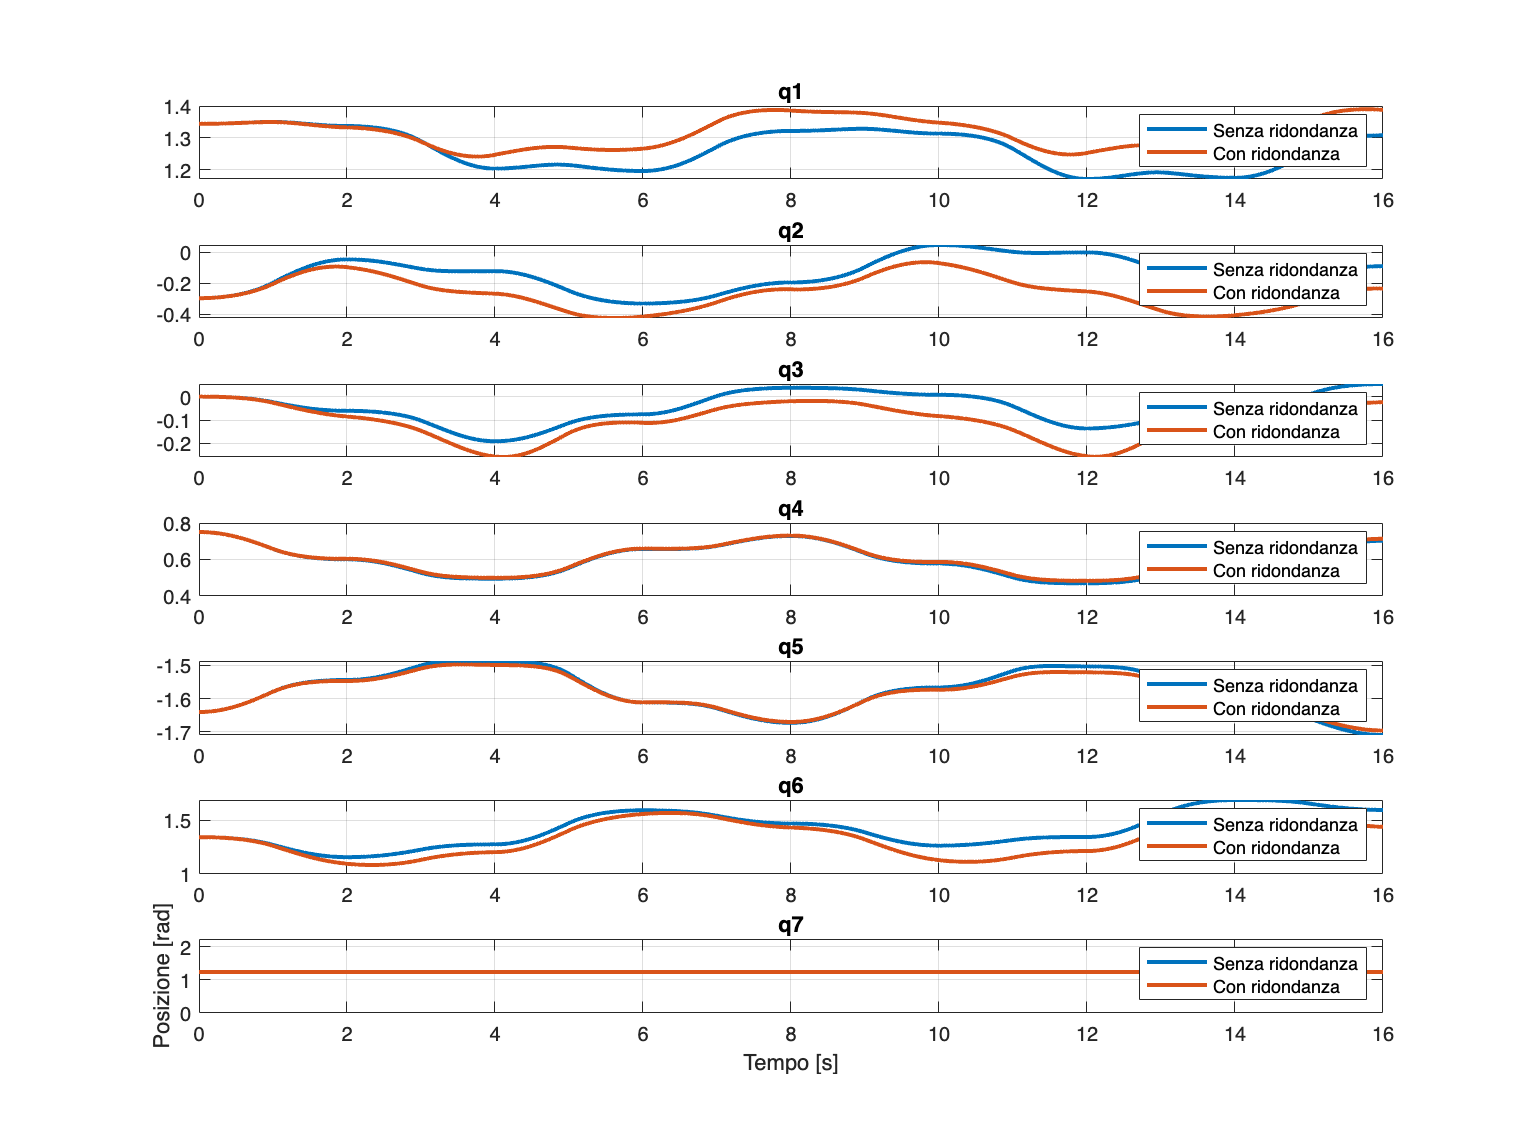


% confronto tra variabili di giunto
figure('Position', [100, 100, 800, 600]);
subplot(7,1,1);
plot(t, q(1,:), t, qr(1,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('q1');
grid on;

subplot(7,1,2);
plot(t, q(2,:), t, qr(2,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('q2');
grid on;

subplot(7,1,3);
plot(t, q(3,:), t, qr(3,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('q3');
grid on;

subplot(7,1,4);
plot(t, q(4,:), t, qr(4,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('q4');
grid on;

subplot(7,1,5);
plot(t, q(5,:), t, qr(5,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('q5');
grid on;

subplot(7,1,6);
plot(t, q(6,:), t, qr(6,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('q6');
grid on;

subplot(7,1,7);
plot(t, q(7,:), t, qr(7,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('q7');
xlabel('Tempo [s]');
ylabel('Posizione [rad]');
grid on;

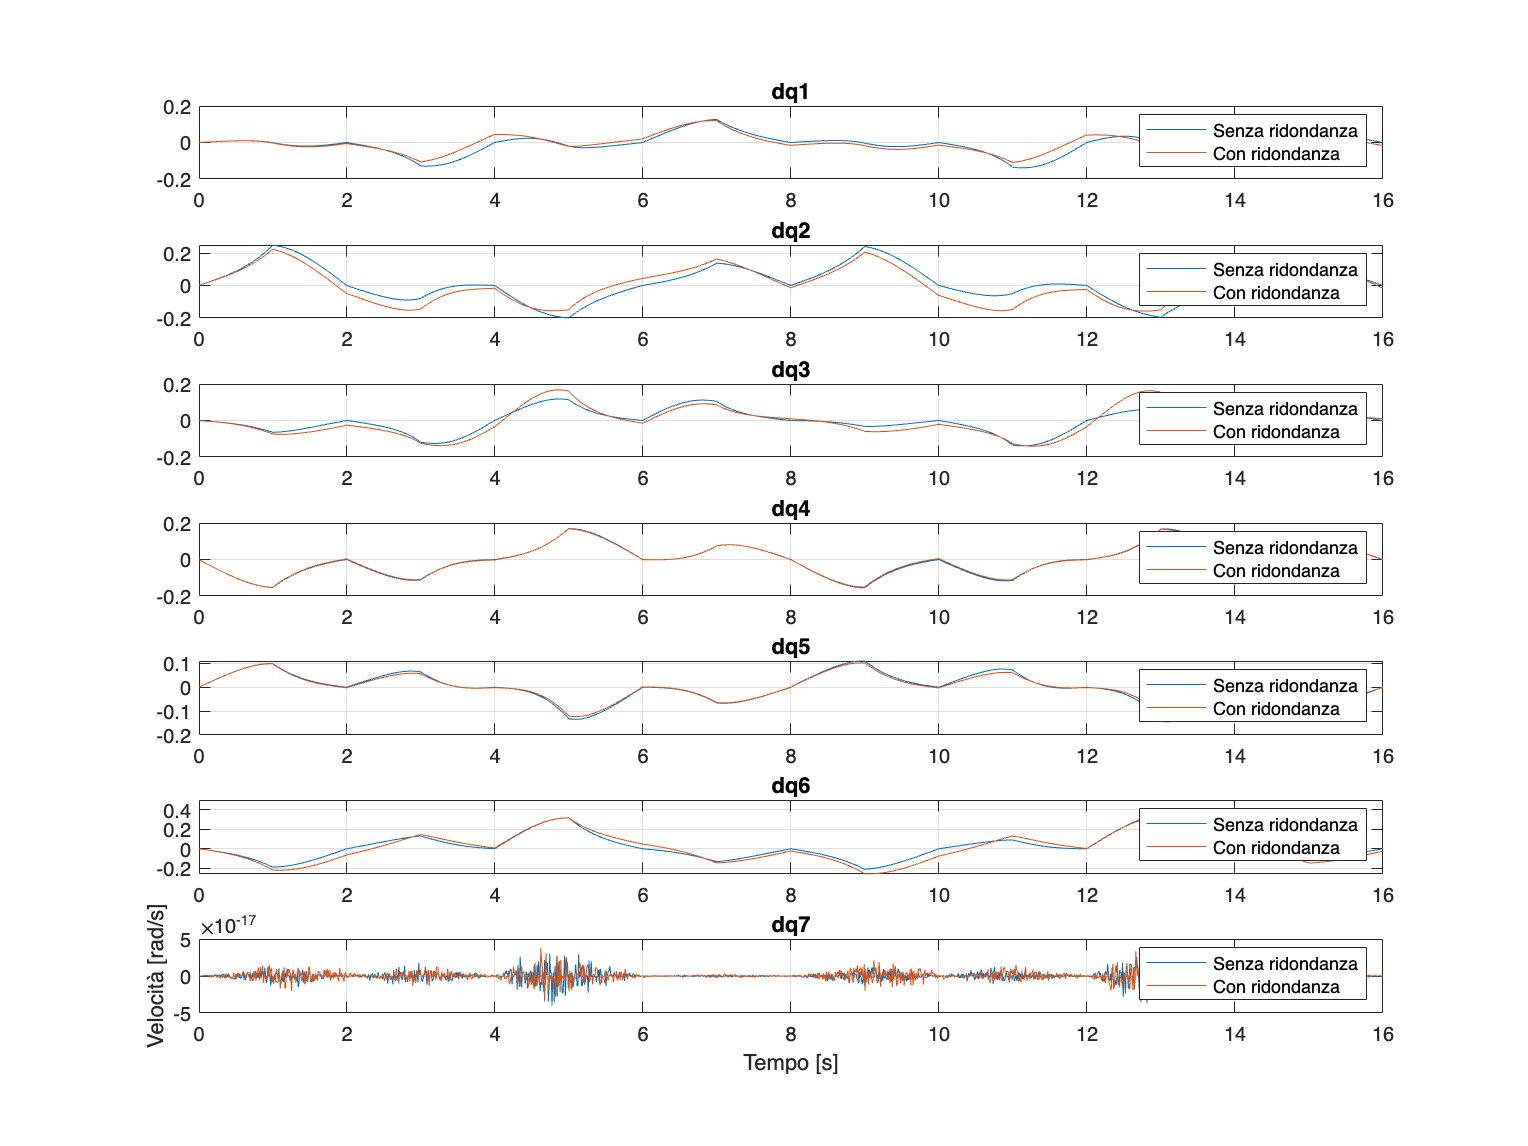


% confronto tra velocità di giunto
figure('Position', [100, 100, 800, 600]);
subplot(7,1,1);
plot(t, dq(1,:), t, dqr(1,:));
legend('Senza ridondanza', 'Con ridondanza');
title('dq1');
grid on;

subplot(7,1,2);
plot(t, dq(2,:), t, dqr(2,:));
legend('Senza ridondanza', 'Con ridondanza');
title('dq2');
grid on;

subplot(7,1,3);
plot(t, dq(3,:), t, dqr(3,:));
legend('Senza ridondanza', 'Con ridondanza');
title('dq3');
grid on;

subplot(7,1,4);
plot(t, dq(4,:), t, dqr(4,:));
legend('Senza ridondanza', 'Con ridondanza');
title('dq4');
grid on;

subplot(7,1,5);
plot(t, dq(5,:), t, dqr(5,:));
legend('Senza ridondanza', 'Con ridondanza');
title('dq5');
grid on;

subplot(7,1,6);
plot(t, dq(6,:), t, dqr(6,:));
legend('Senza ridondanza', 'Con ridondanza');
title('dq6');
grid on;

subplot(7,1,7);
plot(t, dq(7,:), t, dqr(7,:));
legend('Senza ridondanza', 'Con ridondanza');
title('dq7');
xlabel('Tempo [s]');
ylabel('Velocità [rad/s]');
grid on;

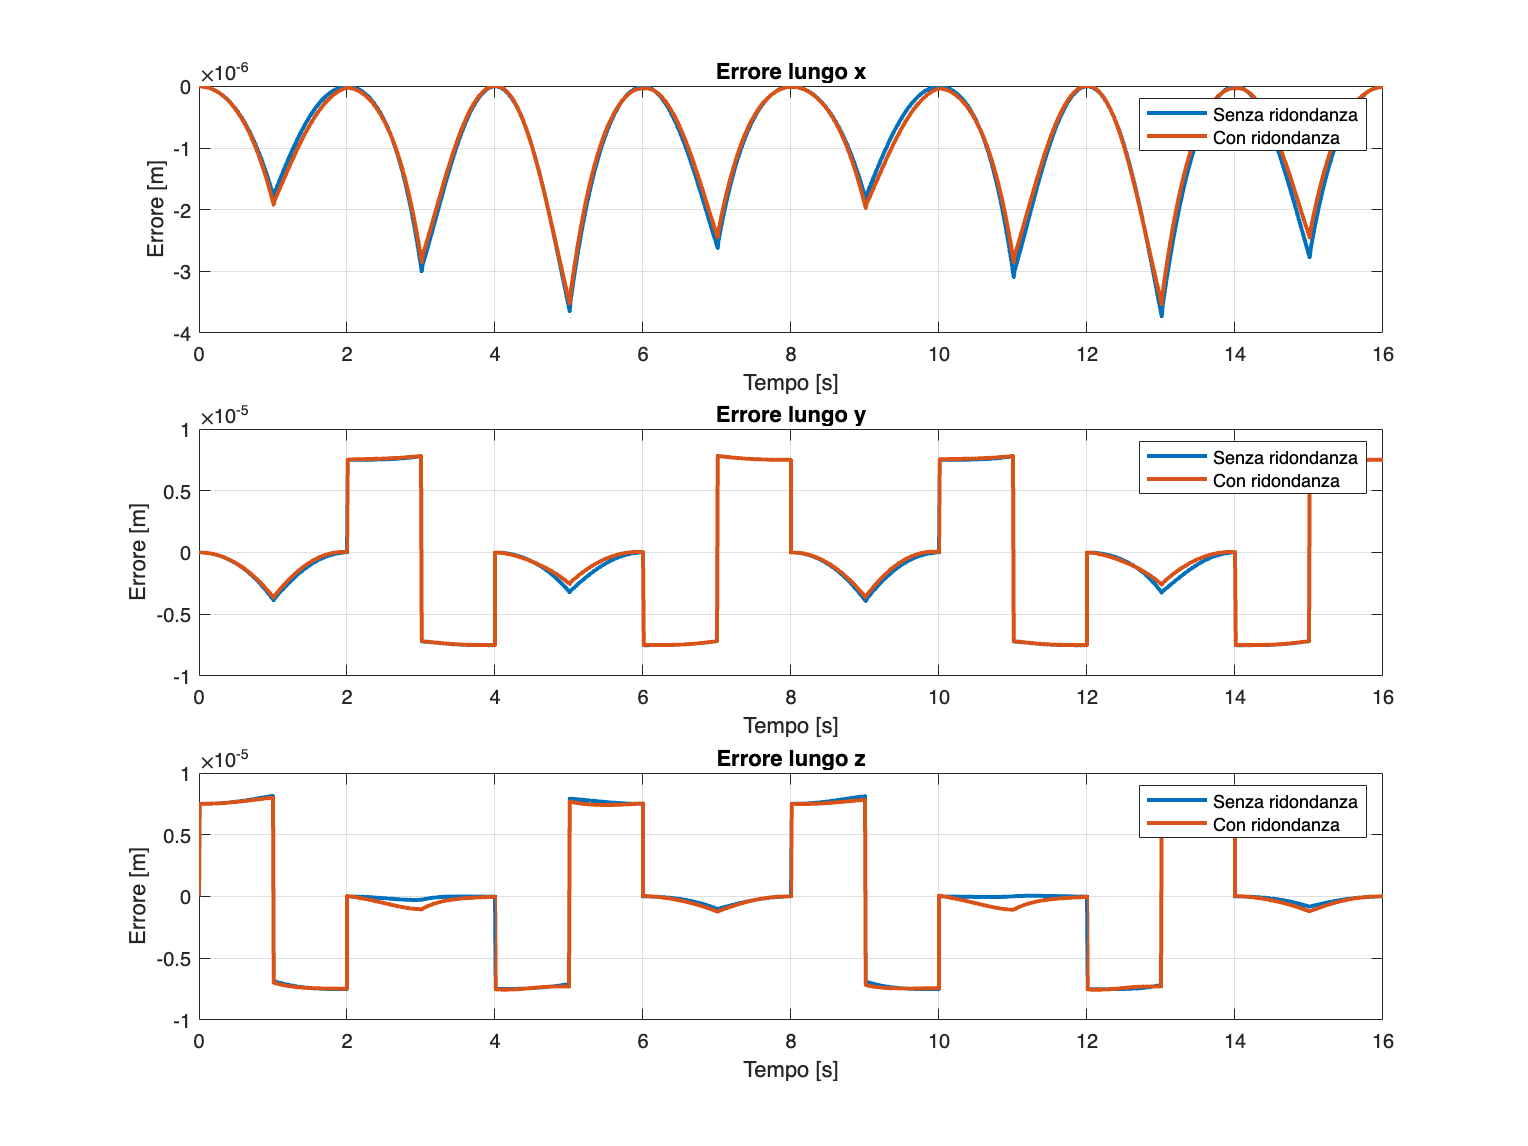


% confronto tra errori di posizione
figure('Position', [100, 100, 800, 600]);
subplot(3,1,1);
plot(t, error(1,:), t, errorr(1,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('Errore lungo x');
xlabel('Tempo [s]');
ylabel('Errore [m]');
grid on;

subplot(3,1,2);
plot(t, error(2,:), t, errorr(2,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('Errore lungo y');
xlabel('Tempo [s]');
ylabel('Errore [m]');
grid on;

subplot(3,1,3);
plot(t, error(3,:), t, errorr(3,:), 'LineWidth', 2);
legend('Senza ridondanza', 'Con ridondanza');
title('Errore lungo z');
xlabel('Tempo [s]');
ylabel('Errore [m]');
grid on;


disp('Posizione iniziale dei giunti:');

Posizione iniziale dei giunti:


disp(q0);

    1.3439
   -0.2967
         0
    0.7505
   -1.6406
    1.3439
    1.2392




disp('Posizione iniziale dei giunti:');

Posizione iniziale dei giunti:


disp(q0);

    1.3439
   -0.2967
         0
    0.7505
   -1.6406
    1.3439
    1.2392

